# TTT4135 MULTIMEDIA SIGNAL PROCESSING Assignment 1

close all;
clear;

## Part 1:

### 1: Still image compression:

#### a)

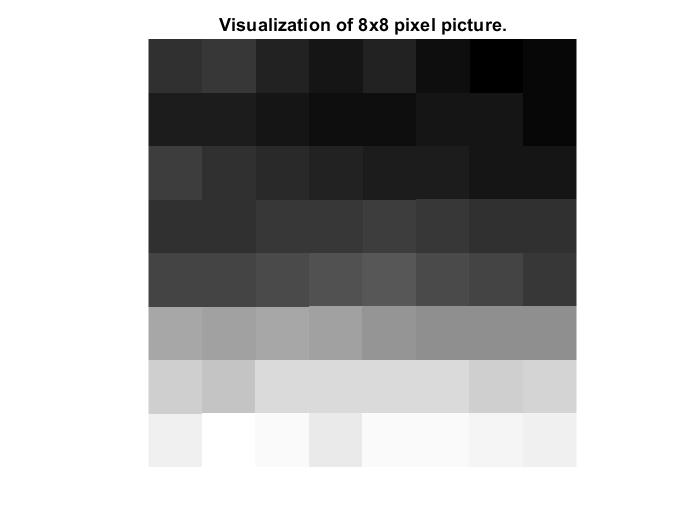

pic_mat =  [124 125 122 120 122 119 117 118
            121 121 120 119 119 120 120 118
            126 124 123 122 121 121 120 120
            124 124 125 125 126 125 124 124
            127 127 128 129 130 128 127 125
            143 142 143 142 140 139 139 139
            150 148 152 152 152 152 150 151
            156 159 158 155 158 158 157 156];

figure()
imshow(log(abs(pic_mat)),[],'InitialMagnification','fit');
title('Visualization of 8x8 pixel picture.')

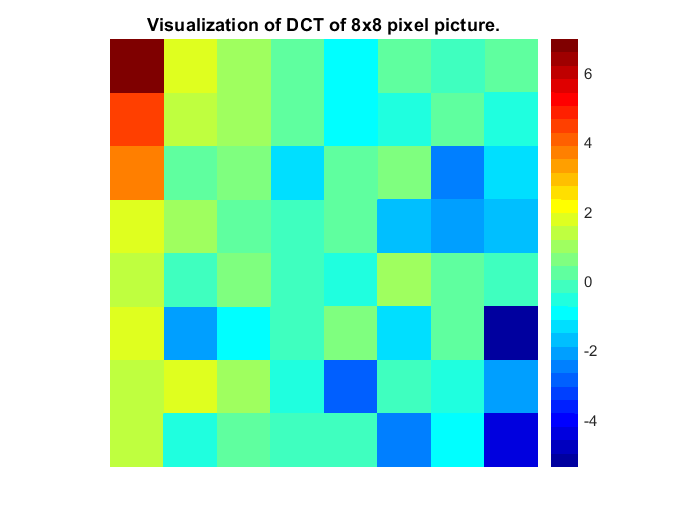

dct_mat = dct2(pic_mat);

figure()
imshow(log(abs(dct_mat)),[],'InitialMagnification','fit');
title('Visualization of DCT of 8x8 pixel picture.')
colormap(gca,jet(32))
colorbar

Here we see that the highest consentration of frequencies in the picutre is in the low frequencies. Elsewhere we have some minor contributions to some of the higher frequency components.

#### b)

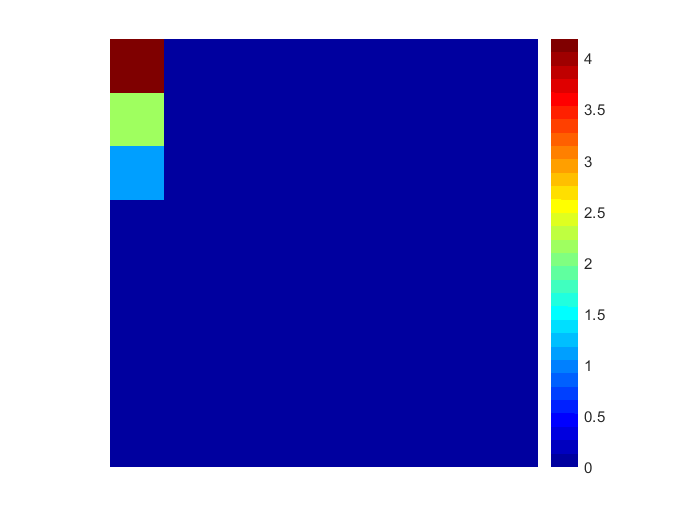

quant_table =  [16 11 10 16  24  40  51  61;
                12 12 14 19  26  58  60  55;
                14 13 16 24  40  57  69  56;
                14 17 22 29  51  87  80  62;
                18 22 37 56  68 109 103  77;
                24 35 55 64  81 104 113  92;
                49 64 78 87 103 121 120 101;
                72 92 95 98 112 100 103  99];

k = floor((dct_mat./quant_table) + 0.5);

figure()
imshow(log(abs(k)),[],'InitialMagnification','fit');
colormap(gca,jet(32))
colorbar

After doing the quantization most of the semi-high and high frequency components have been zeroed out, while the low frequencies are kept.

By encoding/quantizing the image after having done the dct we are able to filter out most of the irrelevant information in the picture. While if we had quantized the picture first, then done the dct it would first have filtered the image by the quantization table, then piced out the low-high frequencie components of the distorted quantized version of the origianl image. Which would not help in reducing the size of the image by removing irrelevancy, it would just make another distorted version if the original image.

#### c)

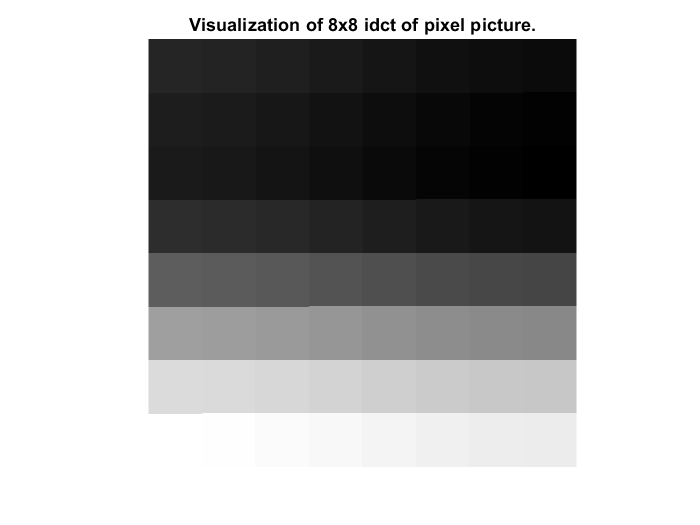

% TODO: ask in help lecture if this is sufficient, or if we have to use
% another formula (same with calculation of PSNR).
dct_mat_inv = ((k).*quant_table);
idct_pic = idct2(dct_mat_inv);

figure()
imshow(log(abs(idct_pic)),[],'InitialMagnification','fit');
title('Visualization of 8x8 idct of pixel picture.')

Based on the following formulas:

$\text{PSNR}_{dB} = 10\cdot \text{log}_{10} \frac{255^2}{\sigma_e^2}$, where $\sigma_e^2 = \frac{1}{MN}\sum_{m=1}^M \sum_{n=1}^N|u(m,n)- \hat u (m,n)|^2$ (from lecture 2, slide 47)

We get the following PSNR:

M = length(pic_mat(:,1));
N = length(pic_mat(1,:));

% Tested if the results were similar with loop and what was done below (it
% was)
% sigma_e2 = 0;
% for m = 1:M
%     for n = 1:N
%         sigma_e2 = sigma_e2 + abs((pic_mat(m,n) - idct_pic(m,n)));
%     end
% end
% sigma_e2 = sigma_e2/(M*N);

sigma_e = (1/(M*N))*sum(abs(pic_mat - idct_pic),'all');
% Not sure if we should use 'abs()' in the above expression, ref. L3-Visual
% compression slide 9.
PSNR = 10*log10((255^2)/(sigma_e^2));
% PSNR2 = 10*log10((255^2)/(sigma_e2^2));
fprintf('PSNR = %f dB\n', PSNR)%, PSNR2)

PSNR = 42.651402 dB


### 2 - Prediction:

#### a)

Given $x(n)
$, with auto-correlation given by $R_x(k) $, with $R_x(0) = \sigma_x, \text{ } R_x(1) = a, \text{ } R_x(k)=0, \text{ for}  \text{ } |k|>1.$

Starting with the Normal Equation we have:


$$\sum_{k=0}^p a_k \gamma_{xx}[n-e] = - \gamma_{xx}[n]
$$


from this we get:


$$a_1 \gamma_{xx}[0] + a_2 \gamma_{xx}[-1] = -\gamma_{xx}[1]$$



$$a_1 \gamma_{xx}[1] + a_2 \gamma_{xx}[0] = - \gamma_{xx}[2]$$


### 3 - Compression Basics:

#### a)

Lossless compression consists of two main steps. The first is using a wavelet or dct transform for redundancy reduction, and the last one is coding the "image" with a lossless coding shceme.

For lossy compression we first have a similar step to the lossless compression, where redundancy is handeled by a wavelet or dct transform, then following that the image is quantized to remove irrelevancy (this is mainly where the loss is introduced) and lastly the image file is coded with a fitting coding scheme.

#### b)

Partly answered in a) 

The process of quantization starts by defining a finite set of allowed values. For a grayscaled picture this would normally be a limitation in the number of bits used to represent each pixel value. Each pixel will there after get a new value as closely corresponding to the original value as possible. Due to the nature of this method, it will no longer be possible to re-transform the image into its original form without errors.

Using DCT or wavelet transform redundancy between neighboring pixels are reduced, while still keeping the key features like edges.

Using wavelet transform produces coefficients equal in number to the amout of pixels in the image. Doing this allows us to concentrate the information in a few coefficients, the ones corresponding to the low frequencies. In doing this, the image can be more easily compressed.

Using DCT produces "blocks" of a set number of pixels for compression. The results of this are that blocky compression artifacts can appear if the DCT compression is too heavy.

#### c)

In most modern applications, DWT is the prefered method as it provides the better compression ration without loss of data. DCT still sees a lot of use however due to it's low processing requirements.

The most common algorithm for DWT is Daubechies wavelets. Type-II DCT is the most common DCT algorithm.

Rate–distortion optimized quantization is the most common quantization algorithm used for lossy compression.

For lossless compression scheme there is a variaty of methods that see widespread use. Some of theses include RLE, Huffman coding, and Arithmetic coding. Specifically for graphics PDF, PNG and JPEG 2000 are some of the more widespread methods.

DCT is the most commonly used method for lossy compression.

#### d)

One can look at the PSNR of the image as we did in 1c, this gives how good the signal strenght in the compressed picture is in relation to the original image.

A more qualitative method to evaluate the compression quality would be through gene expression quantification, transcript alternative splicing and short variants detection.

## Part 2:

### 4 - JPEG and JPEG2000:

#### a)

With the newer JPEG 2000 (J2K) a bunch of new features were introduced into this standard, compared with its predecessor JPEG. 

#### Difference in functionalities:

In J2K there were introduced scalability (where images could be scaled to different formats in a lossless manner from the original image), a more robust error rescilience for broadcasting channels with a high BER, where the PSNR for J2K was slightly higher than for JPEG (ref Table 8, in reading material document 3) for no or low BER, while for higher BER's the difference were more significant. 

J2K also has a functinality for ROI (should possibly be in the next section)

#### Difference in coding techniques:

As J2K uses a wavelet based transform vs JEPG's dct, J2K will not have the same problem with blocking artifacts for lower bit-rate images. 

Im the best